# Min cost flow test

Approximates the halfship assignment problem

## simple example

a=[0 3 5;0 0 4;0 0 0]

a =      0     3     5
     0     0     4
     0     0     0


d=[-3 -2 5]

d =     -3    -2     5


g=[0 1 4;0 0 2;0 0 0]

g =      0     1     4
     0     0     2
     0     0     0



[cost, minf] = netSimplex(a, d, g)

cost = 14

minf =      0     2     1
     0     0     4
     0     0     0


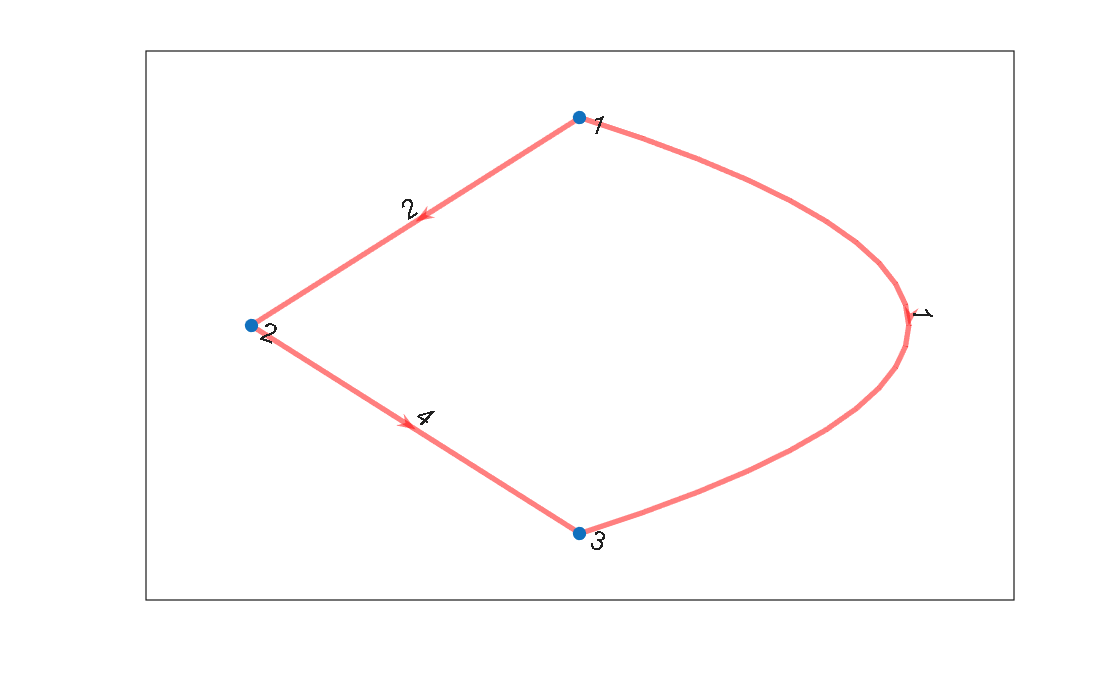


G = digraph(a);
G = digraph(G.adjacency(g(g~=0)));

H = plot(G);
GF = digraph(minf);

H.EdgeLabel = {};
highlight(H,GF,'EdgeColor','r','LineWidth',2);
st = GF.Edges.EndNodes;
labeledge(H,st(:,1),st(:,2),GF.Edges.Weight);

## Halfship assignment Problem

ships = 10;
ast_per_ship = 10;
asteroids = ships * ast_per_ship;

cD_s = ones([1, ships]);
offset = 1;
cD_t = (1 : ships) + offset;
offset = offset + ships;
ci = [];%zeros([ships, (ast_per_ship - 2) * 2]);
for i = 1 : ast_per_ship - 1
    % In vertices
    ci(:, 2 * i - 1) = (1 : ships) + offset;
    offset = offset + ships;

    % Out vertices
    ci(:, 2 * i) = (1 : ships) + offset;
    offset = offset + ships;
end

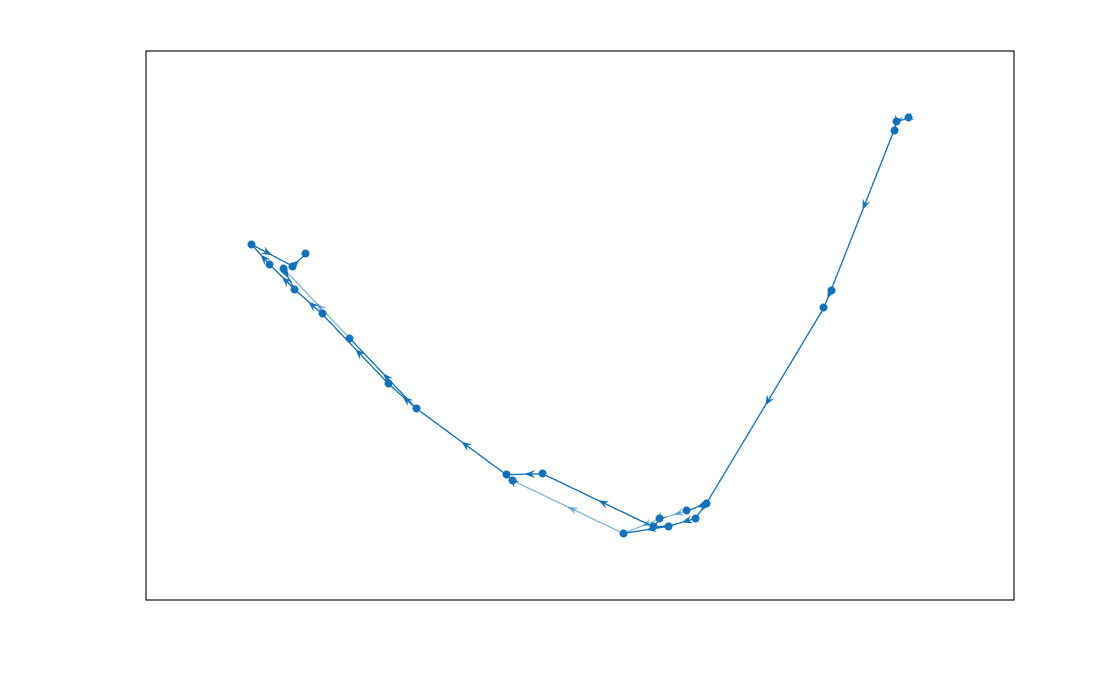

weights = [];

s = [cD_s];
t = [cD_t];
[c1_s_e, c1_t_e] = meshgrid(cD_t, ci(:, 1)');
weights = [weights, randg(1, 1, ships) * 2 + 1];
s = [s, c1_s_e(:)'];
t = [t, c1_t_e(:)'];
weights = [weights, randg(1, 1, ships ^ 2) * 2 + 1];
for i = 1 : ast_per_ship - 2
    s = [s, ci(:, 2 * i - 1)'];
    t = [t, ci(:, 2 * i)'];
    weights = [weights, 1e-3 + zeros(1, ships)];

    [ci_s, ci_t] = meshgrid(ci(:, 2 * i)', ci(:, 2 * i + 1)');
    s = [s, ci_s(:)'];
    t = [t, ci_t(:)'];
    weights = [weights, randg(1, 1, ships ^ 2) * 2 + 1];
end

G = digraph(s, t, weights);
plot(G)


a = full(G.adjacency); % capacity for each arc is 1 (only one ship can go along an edge)
d = [-ships, zeros([1, offset - 1 - 2 * ships]), ones([1, ships])]; % Supply or demand
% probably better way to construct weights
[i,j,s] = find(G.adjacency);
g = full(sparse(i, j, weights, size(a, 1), size(a, 2))); % cost for each arc (delta V)

iters = 1;
if isempty(gcp('nocreate'))
    parpool(5) % open the default pool
end

t1 = tic;
for iter = 1 : iters
    futures(iter) = parfeval(@(a, d, g) netSimplex(a, d, g), 2, a, d, g + iter * 1e-3);
end
t2 = toc(t1);
t2

t2 = 0.0042

t2 / iters

ans = 0.0042

function [] = get_results_and_display_cost(future)
    [cost, minf] = fetchOutputs(future);
    fprintf("Cost %g is %.3f\n", future.ID, cost);
end

afterEach(futures, @(future) get_results_and_display_cost(future), 0, PassFuture = true);

wait(futures)

[cost, minf] = fetchOutputs(futures(1));

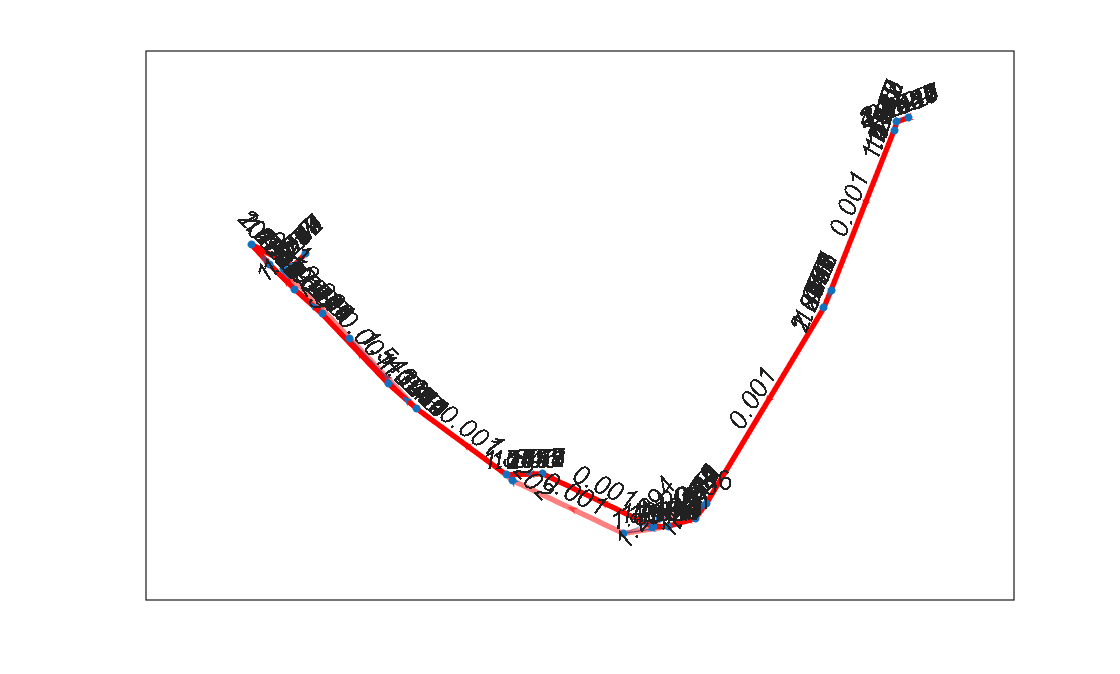


H = plot(G);
GF = digraph(minf);

GF_g = minf .* g;
GF = digraph(GF.adjacency(GF_g(GF_g ~= 0)));

H.EdgeLabel = {};
highlight(H,GF,'EdgeColor','r','LineWidth',2);
st = GF.Edges.EndNodes;
labeledge(H,st(:,1),st(:,2),GF.Edges.Weight);

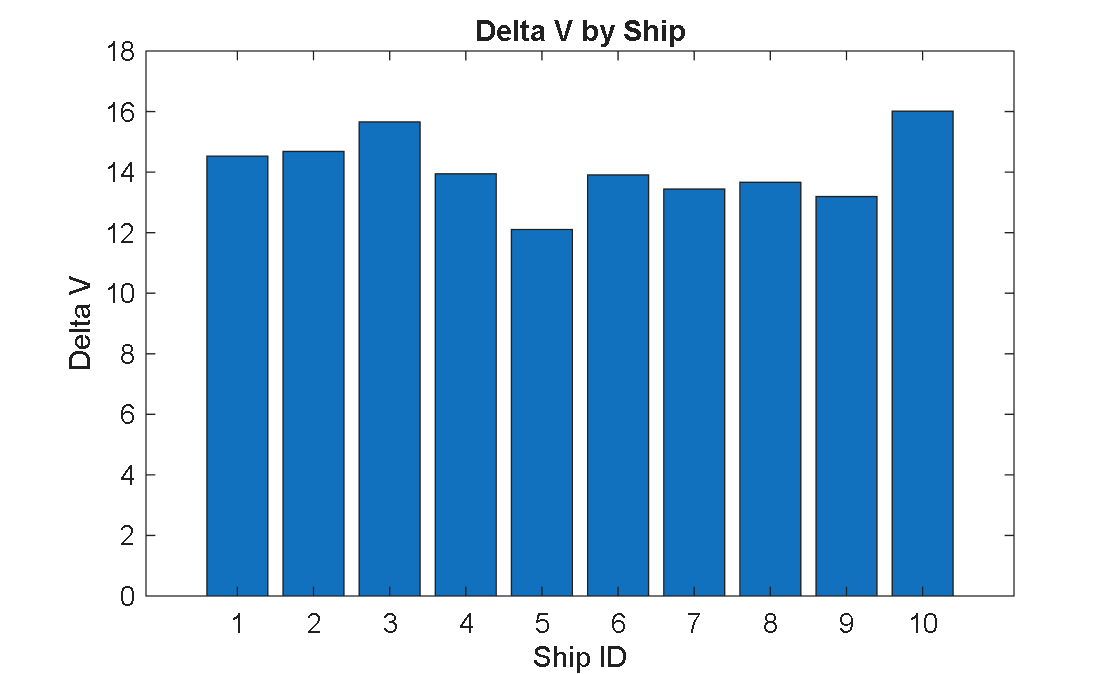

% Get paths for each ship
P = []; % being lazy
d = [];
for ship = 1 : ships
    [P(ship, :), d(1, ship)] = shortestpath(GF,1,size(minf, 1) - ships + ship);
end
P = P';

figure
bar(1 : ships, d);
title("Delta V by Ship")
xlabel("Ship ID")
ylabel("Delta V")

% replace with doing more halffleets
d1 = d;
d2 = d;

Cost = repmat(d1', 1, ships) + repmat(d2, ships, 1);
M = matchpairs(Cost, 1e9);



- Select asteroid group

- Randomly generate halffleets assuming equal asteroid per ship

- Compute least total delta V halfship assignments for each halffleet using min cost flow (network simplex)

- Evaluate feasible halffleet assignments for least delta V using min cost flow (matchpairs)

- Optimize lowest delta V subset of fleets using QCLP (SOCP? or nonconvex)

- Do metaheuristic optimization on fleets

- Periodically update surrogate delta V function by running low thrust on subset of solutions

- Refine timings with low thrust for best solutions at end